Consider the confound of sex.

group1: ratio of numbers of males between sites

group2: ratio of numbers of females between sites

sumGroup: ratio of numbers of subjects between sites

group1vsGroup2: ratio of (male/female) between sites

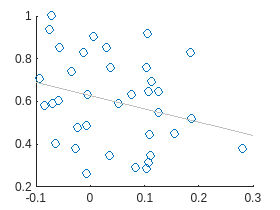

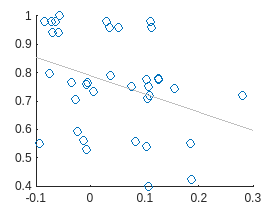

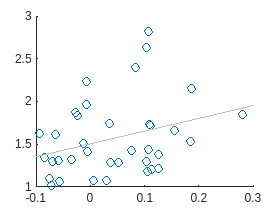

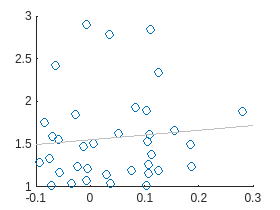

BD


                      group1      group2      sumGroup    group1vsGroup2
                     ________    _________    ________    ______________

    spearman corr    -0.25301     -0.31962      0.2713       0.14466    
    p                0.050211    0.0089593    0.039323       0.20154    



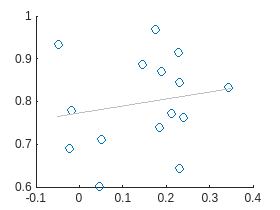

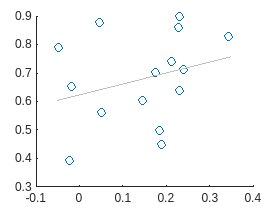

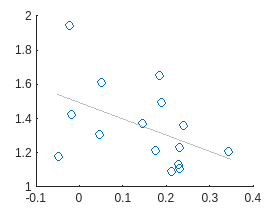

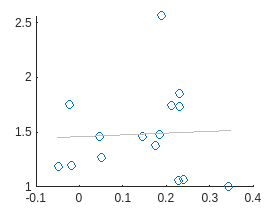

SCA


                      group1     group2     sumGroup    group1vsGroup2
                     ________    _______    ________    ______________

    spearman corr    0.035714    0.30357    -0.41071      -0.078571   
    p                 0.43109    0.21769     0.13819        0.39856   



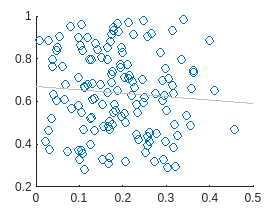

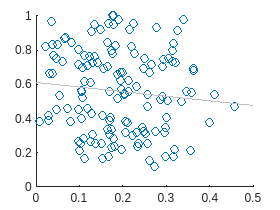

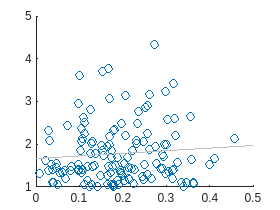

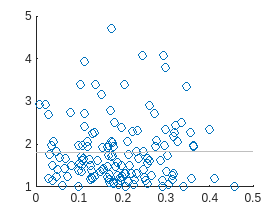

SCZ


                      group1      group2     sumGroup    group1vsGroup2
                     _________    _______    ________    ______________

    spearman corr    -0.069343    -0.1117    0.070155      -0.022404   
    p                  0.23993    0.21416     0.27665        0.41792   



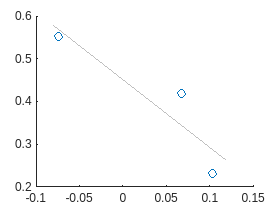

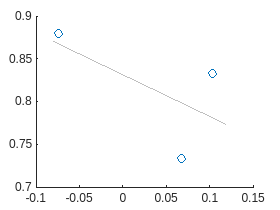

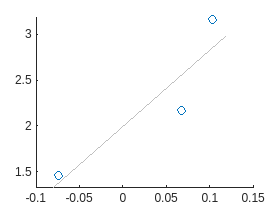

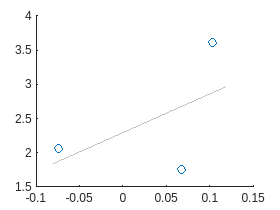

ASD


                     group1    group2     sumGroup    group1vsGroup2
                     ______    _______    ________    ______________

    spearman corr      -1         -0.5       1               0.5    
    p                   0      0.33816       0           0.33286    



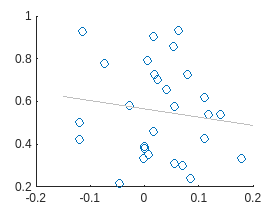

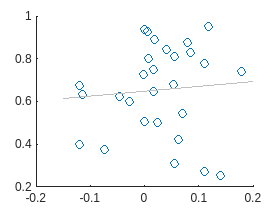

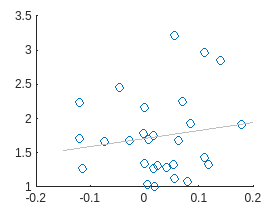

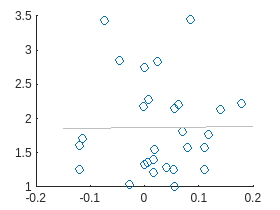

MDD


                      group1      group2     sumGroup    group1vsGroup2
                     _________    _______    ________    ______________

    spearman corr    -0.068711    0.10673    0.095785       0.060755   
    p                  0.35438     0.3379     0.30435        0.36883   



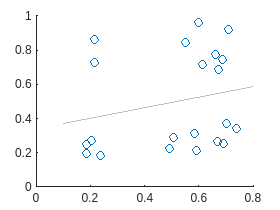

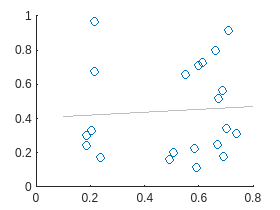

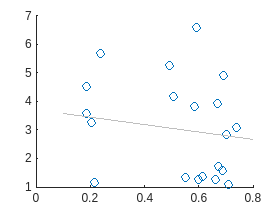

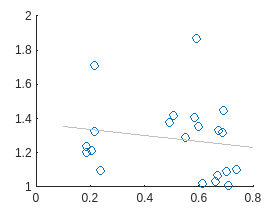

AD


                      group1     group2     sumGroup    group1vsGroup2
                     ________    _______    ________    ______________

    spearman corr     0.35714    0.18052       -0.2        -0.26494   
    p                0.034051    0.22285    0.16837         0.23728   



% Clear all variables and close all figures
clear all
close all

% Initialize parameters
iCOMBAT = 1; % Flag to determine if COMBAT harmonization is used
smoothKernel = 6; % Smoothing kernel size
iter = 5000; % Number of iterations for permutation testing
type = 'spearman'; % Correlation type (Spearman)
diagnosisString = {'BD', 'SCA', 'SCZ', 'ASD', 'MDD', 'AD'}; % List of diagnoses to analyze

nDiag = length(diagnosisString); % Number of diagnoses

% Set the address path based on whether COMBAT harmonization is applied
if iCOMBAT == 1
    address = ['derivatives/s', num2str(smoothKernel), 'COMBAT/'];
else
    address = ['derivatives/s', num2str(smoothKernel), '/'];
end

% Load metadata about demographics and site information
metadata = readtable(['/projects/kg98/trangc/VBM/data/metadataVBM_extended.csv']);
% Load pre-computed correlation matrices and site lists
load(['output/corr_tmap_combat',num2str(iCOMBAT),'_smooth',num2str(smoothKernel),'.mat'], 'cor1', 'cor2',"siteList")

% Loop through each diagnosis
for iDiag = 1:nDiag
    % Compute variance related to sex and site correlation
   [varTable{iDiag} nSite{iDiag}] = cor_var_sex(metadata, ...
       diagnosisString(iDiag), cor1{iDiag}, cor2{iDiag},siteList{iDiag},  iter, type);
% Display results if the variance table is not empty
    if size(varTable,1)~=0
        disp(char(diagnosisString(iDiag))); % Display diagnosis name
        disp(varTable{iDiag}); % Display variance table
        disp(' '); % Add spacing
        disp(' ')
    end
end


% Suppress specific warnings and save the results
warning('off','last')

Error using warning
The last warning issued had an empty warning identifier, or no warnings have yet been issued.

save('output/confound_sex.mat','varTable','nSite')